# 3.3 数值数组的创建和寻访

3.3.1 **行****(****列****)****数组的创建**

- 行（列）数组大致分两类：

**                自变量数组**：元素递增或递减排列；**通用数组****：**元素非有序排列

- 递增/递减型行（列）数组的创建：

                x=a:inc:b                  定步长冒号生成法，inc**缺省**时步长为1

                                                 inc可取正（a<b），也可取负（a>b）

                x=linspace(a,b,n)     在[a,b]区间内产生**线性**等间隔的（1×n）行数组

                                                  n忽略默认为100；若（b-a）不是inc的整倍数

                                                 则最后一个元素的绝对值要小于b的绝对值

                x=logspace(a,b,n)     在10^a至10^b区间内产生**对数**等间隔的（1×n）行数组

                                                  n忽略默认为50

- 一般数组的创建：

                逐个元素输入法；

                运用标准数组生成函数创建行（列）数组，如rand(1,n)，ones(1,n)

- 对行数组实施非共轭转置可得列数组

【例3.1-1】一维数组的常用创建方法举例。

a1=1:6					

a1 =      1     2     3     4     5     6


a11=1:0.5:6

a11 =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000


	a2=0:pi/4:pi			

a2 =          0    0.7854    1.5708    2.3562    3.1416


a3=1:-0.1:0			% a>b, 递减

a3 =     1.0000    0.9000    0.8000    0.7000    0.6000    0.5000    0.4000    0.3000    0.2000    0.1000         0


b1=linspace(0,pi,4)		

b1 =          0    1.0472    2.0944    3.1416


b2=logspace(0,3,4)		    %创建数组[10^0 10^1 10^2 10^3]

b2 =            1          10         100        1000


c1=[2  pi/2  sqrt(3)  3+5i]		  %直接输入

c1 =    2.0000 + 0.0000i   1.5708 + 0.0000i   1.7321 + 0.0000i   3.0000 + 5.0000i


rng default		     %恢复初始设置
c2=rand(1,5)		  %均匀随机分布

c2 =     0.8147    0.9058    0.1270    0.9134    0.6324


d1=randn(1,5)         %正态随机分布

d1 =    -1.3077   -0.4336    0.3426    3.5784    2.7694


d2=ones(1,5)

d2 =      1     1     1     1     1


d3=zeros(1,5)  

d3 =      0     0     0     0     0


g1=d1'               %求列向量

g1 =    -1.3077
   -0.4336
    0.3426
    3.5784
    2.7694


## **3.3.2 ****二维数组的创建**

## **1.** **小规模数组的直接输入法**

- **三个要素：**整个输入数组必须以方括号“[ ]”为其首尾；

                           行与行之间必须用“;”或“Enter”；

                           同行中元素之间必须由“,”或“空格”分隔。

- “;”用在“[ ]”内是行的分隔符，

                在指令末尾表示执行该指令后在屏幕上不显示结果

【例3.1-2】在MATLAB环境下，用下面三条指令创建二维数组C。

a=2.7358; b=33/79;					
C=[1,2*a+i*b,b*sqrt(a);sin(pi/4),a+5*b,3.5+i] %采用表达式

C =    1.0000 + 0.0000i   5.4716 + 0.4177i   0.6909 + 0.0000i
   0.7071 + 0.0000i   4.8244 + 0.0000i   3.5000 + 1.0000i


## **2. ****中规模数组的数组编辑器创建法**  

利用变量编辑器编辑数组后点左键（或Enter）自动保存在工作空间

若要永久保存可用保存菜单或工作区点文件另存为，保存成 .mat文件，需要时加载该文件可在工作空间内生成该数组

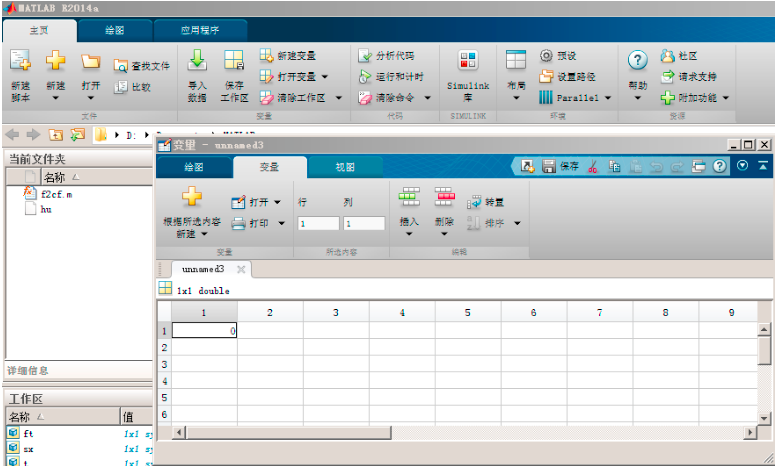

**3.** **中规模数组的****M****文件创建法**

- 对于经常需要调用的数组，当数组规模较大且复杂时，可建立M文件。

                以后每当需要该数组时，只要运行M文件，就可在内存中生成该数组。

- 打开文件编辑器，填写框中输入所需数组并保存。

                最好在文件的首行，编写文件名和简短说明，以便查阅。

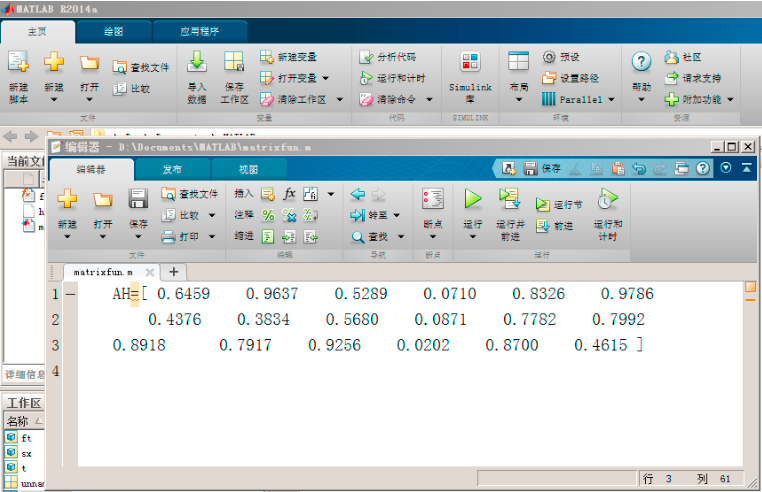

**4.** **利用****MATLAB****函数创建数组**

MATLAB提供生成特殊数组的函数，并可以对其做修改运算等加工

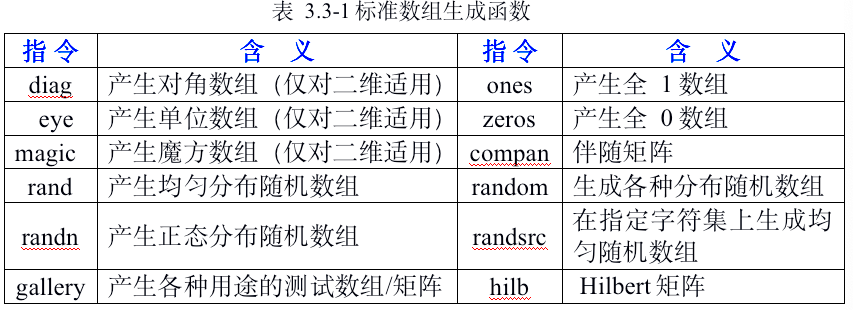

【例3.2-5】利用最常用标准数组生成函数产生标准数组的演示。

ones(2,4)				   % ones(m,,n)产生（m×n）全1数组

ans =      1     1     1     1
     1     1     1     1


rng(0,'v5normal')		%把正态随机数发生器置0
randn(2,3)			   % randn(m,n)产生（m×n）正态随机矩阵

ans =    -0.4326    0.1253   -1.1465
   -1.6656    0.2877    1.1909


D=eye(3)			      % eye(m,,n)产生（m×n）单位数组，主对角线为

D =      1     0     0
     0     1     0
     0     0     1


diag(D)		%diag(A,k)：A为向量，以向量作为第k条对角线构成数组，

ans =      1
     1
     1


             %k=0（默认）主对角线,k>0/k<0为主对角线上/下方第k条对角线
             %A为矩阵，提取矩阵的第k条对角线构成列向量
diag(diag(D))	

ans =      1     0     0
     0     1     0
     0     0     1


randsrc(3,20,[-3,-1,1,3],1)    %在[-3,-1,1,3]上产生3×20均布随机数组

ans =     -1    -1    -3     1    -3     1    -3     3     3    -3    -3     1     1     3    -1    -1    -1     1    -1    -3
     1    -3    -1    -1     3    -1    -3    -1     3    -3    -1     1     3     3     3     3    -3    -3    -3     1
    -3    -3    -1     1    -3     1     3     1    -3     3     3    -1    -3     1    -3    -1    -3    -1     1     1


                               % 随机发生器的状态设置为1

**3.3.3 ****二维数组元素的编址和寻访**

二维数组的编址、寻访概念及其方法可以推广到高维数组中去。

**1****、 二维数组元素的编址**

  编址方法有全下标编址(Subscripts)和单序号编址(Single Index)两种。

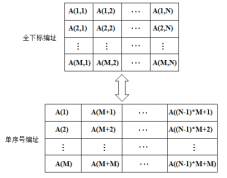

全下标编址和单序号编址的转换指令如下：

**[rawsub,colsub]=****ind2sub****(****A****rray****S****ize,IND)    **单序号编址转换成全下标编址

**IND=****sub2ind****(ArraySize,raw****S****ub,col****S****ub)**     全下标编址转换成单序号编址

〖说明〗

- ArraySize是表示数组规模（行规模和列规模）的一个“二元数组”，第一个元素是行规模，第二个元素是列规模，通常用size指令获取

- IND是K个所感兴趣元素单序号构成的（1×K）或（K×1）数组

- rawsub和colsub是所感兴趣元素全下标编址的“行下标数组”和“列下标数组”。 两数组规模应相同，或都是（1×K）或都是（K×1）数组。

【例】

A=[1,2,3,4;5,6,7,8;9,10,11,12]

A =      1     2     3     4
     5     6     7     8
     9    10    11    12


sub2ind(size(A),2,2)

ans = 5

a=sub2ind(size(A),[1,2;3,3],[1,1;2,3]) 

a =      1     2
     6     9


           %数组中可以有“;”,行(列)号顺序不变,但两数组必须相同，显示数组与之同

**2. 二维数组元素的寻访**

- 按址寻访方：全下标寻访，单序号寻访

- 按条件寻访：

                编写条件表达式NLR(A)，

                生成规模与A相同的**逻辑数组**L，

                采用A(L)格式，由L中1元素寻访出A中满足条件的所有元素

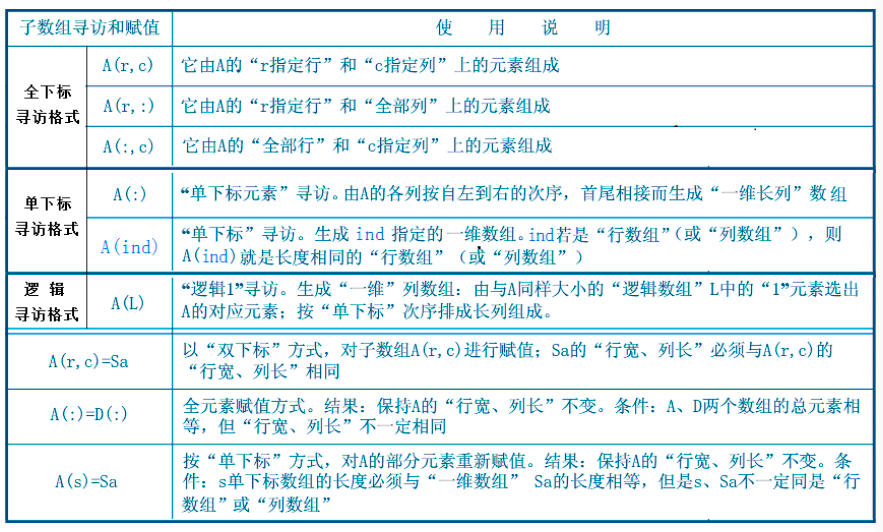

【例3.3-6】本例演示：数组元素及子数组的各种标识和寻访格式；

A=zeros(2,6)		

A =      0     0     0     0     0     0
     0     0     0     0     0     0


a=3:14

a =      3     4     5     6     7     8     9    10    11    12    13    14


A(:)=a(:)		   % 单下标法：单下标全元素赋值

A =      3     5     7     9    11    13
     4     6     8    10    12    14


A(:)=3:14

A =      3     5     7     9    11    13
     4     6     8    10    12    14



A(2,4)			      % 全下标法：指定行、指定列

ans = 10

A(8)			         % 单下标法：单下标寻访

ans = 10


A(:,[1,3])	      % 全下标法：全部行、指定列

ans =      3     7
     4     8


A([1,2,5,6]')	   % 单下标法:生成指定的列（或行）数组

ans =      3
     4
     7
     8



A1=A(:,4:end)	   % 全下标法：全部行、指定列，end表示最后一列。

A1 =      9    11    13
    10    12    14


A2=A(4:end)      % 单下标法，end表示最后一个元素

A2 =      6     7     8     9    10    11    12    13    14



A(2,1:2:5)=[-1,-3,-5]		 % 全下标法：指定行、指定列赋值

A =      3     5     7     9    11    13
    -1     6    -3    10    -5    14



B=A([1,2,2,2],[1,3,5] )   % 全下标法：指定行、指定列。

B =      3     7    11
    -1    -3    -5
    -1    -3    -5
    -1    -3    -5


% 可重复指定行列

按条件寻访：

L=A<=0        %根据逻辑判断条件生成与A同规模的数组

L = 2×6 logical 数组
   0   0   0   0   0   0
   1   0   1   0   1   0


AL=A(L)       %由与A同大小的L中的1选出

AL =     -1
    -3
    -5


A(L)=NaN      %对满足逻辑关系的元素置NaN

A =      3     5     7     9    11    13
   NaN     6   NaN    10   NaN    14


isnan(A)     %将数组A中的nan位置置1其余置0

ans = 2×6 logical 数组
   0   0   0   0   0   0
   1   0   1   0   1   0


## **3.3.4 ****数组构作技法综合**

利用MATLAB提供的反转、插入、提取、收缩、重组等操作，

可生成比较复杂的数组，也可以对已生成的数组进行修改、扩展。

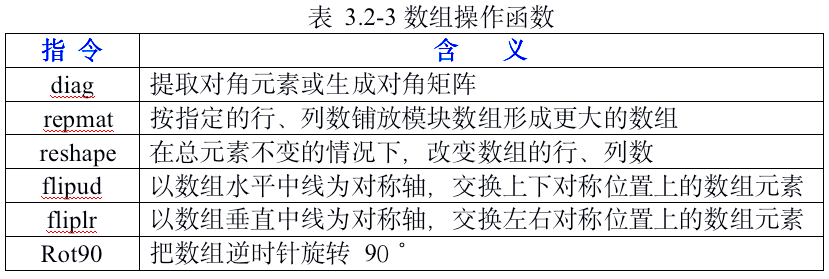

【例 3.2-7】数组操作函数reshape、diag、remat的用法。

a=1:8					

a =      1     2     3     4     5     6     7     8


A=reshape(a,4,2)		

A =      1     5
     2     6
     3     7
     4     8


A=reshape(A,2,4)		  %改变行数和列数

A =      1     3     5     7
     2     4     6     8



b=diag(A,2)			     % 提取对角元素。

b =      5
     8


B=diag(b)			     % 生成对角阵

B =      5     0
     0     8



D1=repmat(B,2,4)	  % 排列B模块

D1 =      5     0     5     0     5     0     5     0
     0     8     0     8     0     8     0     8
     5     0     5     0     5     0     5     0
     0     8     0     8     0     8     0     8



D1([1,3],: )=[ ]	  % 删除指定行/列；空阵[]删除子数组的用法

D1 =      0     8     0     8     0     8     0     8
     0     8     0     8     0     8     0     8


【例3.2-8】函数flipud, fliplr, rot90对数组的操作体现着“矩阵变换”。

A=reshape(1:9,3,3) 

A =      1     4     7
     2     5     8
     3     6     9


B=flipud(A) 	          % 上下对称交换

B =      3     6     9
     2     5     8
     1     4     7


C=fliplr(A)	          % 左右对称交换

C =      7     4     1
     8     5     2
     9     6     3



D=rot90(A,2)	                      % 逆时针旋转90度，2次

D =      9     6     3
     8     5     2
     7     4     1


# 3.4 “非数”和“空”数组 

MATLAB	中特有的两个概念和“预定义变量”

## 3.4.1 非数NaN （或记为nan）

由$\frac{0}{0}, \quad \frac{\infty}{\infty}, \quad 0 \times \infty, \quad \infty-\infty$等运算产生

【NaN的**性质**】

- NaN参与运算所得的结果也是NaN，即具有**传递性**；

- 0NaN没有“大小”概念，不能比较两个NaN的大小。

【NaN的**功用**】

- 真实记述$\frac{0}{0}, \quad \frac{\infty}{\infty}, \quad 0 \times \infty, \quad \infty-\infty$等运算的后果；

- 避免可能因$\frac{0}{0}, \quad \frac{\infty}{\infty}, \quad 0 \times \infty, \quad \infty-\infty$等运算而造成程序执行的中断；

- 在测量数据处理中，可以用来标识“野点（非正常点）”；

- 在数据可视化中，可以**裁剪图形**。

【例3.4-1】非数的产生和性质演示。

**（****1****）非数的****产生**

a=0/0,b=0*log(0),c=inf-inf  

**（****2****）非数的****传递性**

0*a,sin(a) 

**（****3****）非数的属性判断**

class(a)		 % 判断数据类型
isnan(a)		%    唯一判断非数的指令，

【例3.4-2】非数元素的寻访。

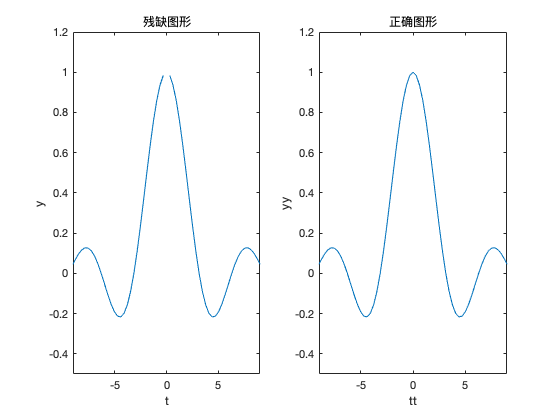

rng default	% 恢复启动时的默认全局随机流
R=rand(2,5);R(1,5)=NaN;R(2,3)=NaN  

LR=isnan(R)			    % 对数组元素是否非数进行判断
si=find(LR)						  % 确定非数的“单下标”标识
[ri,ci]=ind2sub(size(R),si)	  % 转换成“全下标”标识

[rj,cj]=find(LR)		          % 直接确定非数的全下标
disp('非数在二维数组R中的位置')
disp(['单下标时的第',int2str(si(1)),'和第',int2str(si(2)),'个元素']) 

## **3.4.2 ****“空”数组 **

定义：数组的某维长度为0或若干维长度均为0。用一对方括号 [ ] 表示“空”数组是MATLAB为操作和表述需要而专门设计的一种数组。

**功用****: **    ① 在没有"空"数组参与运算时, 

                计算结果中的"空"可以合理地解释"所得结果的含义"

            ②运用"空"数组对其他非空数组赋值, 

                可以改变数组的大小, 但不能改变数组的维数

                全部元素删除变为空数组

〖说明〗

- 不要把“空”数组与全零数组混淆。这是两个不同的概念。 

- 不要把“空”数组看成“虚无”，它确实存在。

                利用which、who、whos及内存变量浏览器可以验证它的存在。 

- 唯一能正确判断一个数组是否“空”数组的指令是isempty(X)。 

- “空”数组在运算中不具备传递性。

                对运算中出现的“空”结果，解释要谨慎

【例3.4-3】关于“空”数组的算例。

（1）创建“空”数组的几种方法

a=[]              % 二维“空”（行、列长度均为0）数组
b=ones(2,0)
c=zeros(2,0)      %“空”数组不同于全零数组
d=eye(0,2)
f=rand(2,3,0,4)   % 4维数组

（2）“空”数组的属性

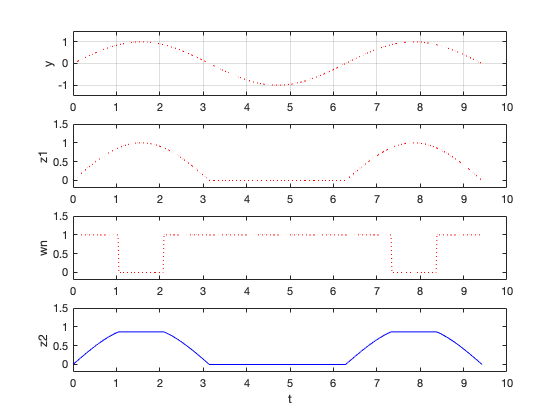

class(a)			   % 数据类型
isnumeric(a)		% 是数值数组吗？
isempty(a)		    %  唯一可正确判断数组是否“空”的指令

which a 			  % 显示变量a信息
ndims(a)			  % 维数

size(a)			  % 注意：“空”数组并非“虚无”，它确实存在。

（3）“空”数组用于子数组的删除和大数组的大小收缩

A=reshape(-4:5,2,5)  
A(:,[2,4])=[]

A(:,:)=[]  

# 3.5 关系操作和逻辑操作

       ** MATLAB**约定：

- 关系（或逻辑）表达式中，作为输入的**任何非****0****数都被看作是“逻辑真”**

                而只有0才被认为是“逻辑假”。

- 计算结果(**输出****)****是****由****0****和****1**组成的“逻辑数组”。1表示“真”，0表示“假”

- 逻辑数组（Logical Array）是一种**特殊的数值数组**。

                与“数值类”有关的操作和函数对它同样适用。

 **3.5.1** **关系操作**

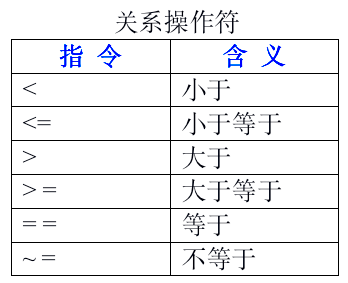

 〖说明〗

- 标量可以与任何维数组进行比较。比较在标量与数组每个元素之间进行

                比较结果将与被比较数组同维

- 当比较量中没有标量时，关系符两端进行比较的数组必须维数相同

                比较在两数组相同位置上的元素间进行，因此比较结果与被比数组同维

 【例3.5-1】关系运算示例。

 
A=1:9,B=10-A
r0=(A<4)    % 比较结果将与参与比较的数组同维。
r1=(A==B)   % 进行比较的两数组必须维数相同 

 【例3.5-2】关系运算应用。

通过对函数**sint/t**运算及作图展示关系运算及非数nan的应用。

t=-3*pi:pi/10:3*pi;	% 自变量数组中，存在0值
y=sin(t)./t;			% 在t=0处，将产生非数。
tt=t+(t==0)*eps;		% 使0元素被一个“机器零”小数代替
                   % 逻辑数与数值数相乘
yy=sin(tt)./tt;		% 用sin(eps)/eps近似替代sin(0)/0极限
subplot(1,2,1),plot(t,y),axis([-9,9,-0.5,1.2])        
% 非数nan在绘图中的剪裁作用
xlabel('t'),ylabel('y'),title('残缺图形') 
subplot(1,2,2),plot(tt,yy),axis([-9,9,-0.5,1.2])
xlabel('tt'),ylabel('yy'),title('正确图形') 

**3.5.2 ****逻辑操作**

逻辑操作的引入，使复杂关系运算成为可能。

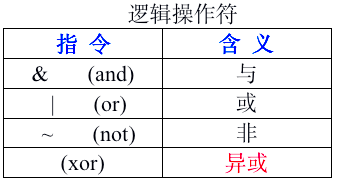

〖说明〗

- 运算符&、|、~与函数and、or、not等价

- 标量可与任何维数组进行逻辑运算。

                运算在标量与数组每个元素间进行，运算结果与参与运算的数组同维

- 当逻辑运算中没有标量时，参与运算的数组必须维数相同。

                逻辑运算在两数组相同位置上的元素间进行

【例3.5-3】逻辑操作和关系操作。本例演示：逻辑、关系操作的组合。 

（1） 逻辑、关系操作的组合

A=[-2,-1,0,0,1,2,3]
L1=~(A>1)		  % 哪些元素不大于1？
L2=(A>0)&(A<2)  % 哪些元素大于0且小于2？

（2）xor的作用

A,B=[0,-1,1,0,1,-2,-3]
C=xor(A,B)  	 

【例3.5-4】试绘制如图3.5-2最下那幅子图所示的“**正弦波**$\mathrm{sin}\text{ }t$**的削顶半波整流波形**”，

削顶发生在每个周期的[${60}^o ,{120}^o$]之间。本例演示：逐段解析函数的计算和表现。

clear,t=linspace(0,3*pi,500);y=sin(t);
z1=((t<pi)|(t>2*pi)).*y;					  % 获得整流半波
w=(t>pi/3&t<2*pi/3)+(t>7*pi/3&t<8*pi/3);  % 关系逻辑运算和数值运算
wn=~w;	
z2=w*sin(pi/3)+wn.*z1;                    % 获得削顶整流半波
subplot(4,1,1),plot(t,y,':r'),axis([0,10,-1.5,1.5]) 
ylabel('y'),grid on
subplot(4,1,2),plot(t,z1,':r'),axis([0,10,-0.2,1.5]),ylabel('z1')
subplot(4,1,3),plot(t,wn,':r'),axis([0,10,-0.2,1.5]),ylabel('wn')
subplot(4,1,4),plot(t,z2,'-b'),axis([0,10,-0.2,1.5]),ylabel('z2')
xlabel('t')  